# 異質陣列 (cell)

看到 cell，就先想到 excel 的 cell，就想到一張 excel 表，這會是最直覺的思考方式

為啥叫異質陣列，因為 excel 的表，每一個 cell，你要塞什麼資料型態的內容進去，都可以。

舉例來說，以前學的 2-d array，如下：

% 2-d array
A = [1, 2, 3; 4, 5, 6]

A =      1     2     3
     4     5     6


他的內容，全都要是一樣的資料型態

但現在，我如果用 cell array 來做，就只要把中括號改大括號，裡面每個 element，就都可以隨我高興寫不同的 type 了

B = {'hank', 185, 82; 'pinpin', 160, 46}

B = 2×3 cell array
    {'hank'  }    {[185]}    {[82]}
    {'pinpin'}    {[160]}    {[46]}


可以看到，我有的 cell，是 string，有的 cell，是 double

而且，看起來其實就超像 table 的。差別只在，他沒有欄位名稱。

由這邊可以很快的歸納 3 件事：

- 如果要存 table 類型的資料，可以用 cell array，而不是一般的 array (對比 python，就是 cell array 就是閹割版的 pd.DataFrame(因為沒有欄位名稱), 一般的 array 就是 python 的 numpy array)

- 因為沒有欄位名稱，所以可以想像，要取資料時，都是用 indexing 的方式做，也就是第幾 row，第幾 column 的方式來取資料，而不會是用欄位名稱取資料

- 大括號 { }，和 python 的 dictionary 完全沒關係，不要用 key-value 的想法去想他。他只是因為 matlab 中，已經用 [ ] 來表示一般 array 了，所以用 { } 來做個區別而已。

再看一個課堂上的例子：

cell array -> 把異質的資料格式，都存在同一個矩陣裡面 -> 異質矩陣

clear
load('materials_L4/ExampleCell.mat')

資料讀進來後，去 matlab 的左邊 workspace，點開 NC 這個變數 (Normal Control group 的意思，對照組的資料)，他是一個 31x7 的 cell array (所以他仍是 array, 但他多加了個 cell ，就可以儲存不同格式的資料)。

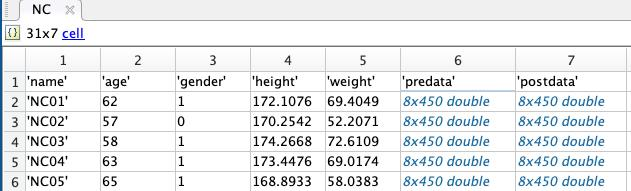

可以看到，每一個 cell，他都可以存不同格式的資料，例如 {1,1} 是 string, {2,2} 是 dobule, {2, 6} 甚至是 8x450 的 2-d array

我們如果把 {2, 6} 這一個點兩下，就可以看到他存的真的是 2-d array

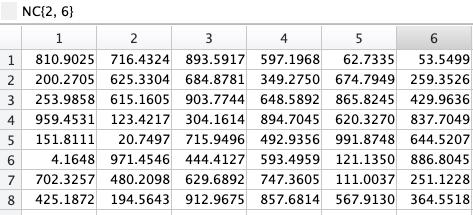

所以，這邊除了再次驗證剛剛的想法：cell array 是個閹割版的 pd.DataFrame (沒有欄位名稱) 之外，又得到新 idea:  

- cell 可以很彈性，裡面可以放一般的純量(如字串, double)，也可以放一般的 array，當然，你也可以放在放 cell array，所以他的 cell 是可以一直 nested 下去的。

## 建立異質陣列

### 用 大括號 建立 cell array

% 2-d cell array
A = {'1', 2, [3,3]; 4, [1 2 3; 4 5 6; 7 8 9], 6i}

上面的表格，是受惠於 live editor 幫你美化的結果。實際上，在 command window，他的結果如下：

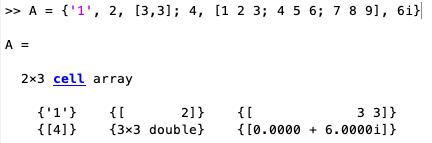

可以清楚看到，A 還是個 array，但他的每個 element，都被 `{}` 給包住，是一個 cell

可用 `iscell()` 來確認是否為異質陣列

class(A)

A = 2×3 cell array
    {'1'}    {[       2]}    {[             3 3]}
    {[4]}    {3×3 double}    {[0.0000 + 6.0000i]}


iscell(A)

### 用 content indexing 來做

A = cell(2,2) % 先建立一個空的 2x2 異質陣列

ans = 'cell'

A{1,1} = 'This is the first cell.'; % string 的 data type

ans = logical
   1


A{1,2} = [5+j*6 , 4+j*5]; % 1*2 的複數陣列
A{2,1} = [1 2 3; 4 5 6; 7 8 9]; % 3*3 的整數陣列

A = 2×2 cell array
    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}


A{2,2} = {'Tim'; 'Chris'}; % 2*2 的異質陣列
A

## 異質陣列的顯示

最簡單的方式，是善用 matlab 的 IDE，我直接點 Workspace 的變數，就會 show 出漂亮的結果了。

如果想在 command window 看結果，可以用 `cellplot()` 來看他的結構

cellplot(A)

但我們也可從上面的範例看出，如果 cell 裡面，不是單一元素的結構，而是還有另一個 array，那他不會顯示出結果

這時，可以用 `celldisp()` 來牆破它顯示出所有 element 的內容

celldisp(A)

或是，你想看啥，就直接把那個 cell 取出來，那就看得到他的長相了

A{2,2}

A = 2×2 cell array
    {'This is the first cell.'}    {[5.0000 + 6.0000i 4.0000 + 5.0000i]}
    {3×3 double               }    {2×1 cell                           }


## 異質陣列的取用

### 取值 (大括號取值是取到 cell 裡面的內容，小括號取值是取整個 cell)

之前在 array 的取值時，都是用小括號取值，例如這樣：

A = [1, 2, 3; 4, 5, 6]
A(1,1)

但，如果今天是 cell array，你用小括號取值，他會把整個 cell 取出來給你：

B = {'hank', 185, 82; 'pinpin', 160, 46};

 
A{1,1} =
 
This is the first cell.
 
 
A{2,1} =
 
     1     2     3
     4     5     6
     7     8     9

 
 
A{1,2} =
 
   5.0000 + 6.0000i   4.0000 + 5.0000i

 
 
A{2,2}{1} =
 
Tim
 
 
A{2,2}{2} =
 
Chris
 


res = B(1,1);
res

ans = 2×1 cell array
    {'Tim'  }
    {'Chris'}


class(res)

這其實不一定是我要的，因為，我要的是 cell 裡面的內容。所以，我可以用大括號取值，就會取到 cell 裡面的 value

res = B{1,1};

A =      1     2     3
     4     5     6


res

ans = 1

class(res)

### nested 取值

剛剛的 NC 這個變數，cell 裡面，還有 array，那就一路 chain 下去

NC{2,6}(1:3, 1:3)

### slicing

當我們做 slicing 時，其實我們要的是取 `sub cell array` 的意思，所以，照剛剛的邏輯，我現在應該要用小括號來取才對 (因為小括號是取整個 cell)

如果你用大括號來做 slicing，因為大括號是吐 cell 裡的值給你，所以他現在會把 sub cell 裡的值全部吐出來。

整理一下：

- 用小括號，才是想像中 slicing 的結果：就是回給你 sub cell array

- 如果用大括號，他會把所有cell分別吐出來，你要 assign 給多個 variable 去接

B = {'hank', 185, 82; 'pinpin', 160, 46}
names = B(:,1)

res = 1×1 cell array
    {'hank'}


[name1, name2] = B{:,1}

ans = 'cell'

## Concatenation

和 array 的 concatenation 一樣，都是用中括號包起來。如果 rbind 就加 分號這樣：

B = {'hank', 185, 82; 'pinpin', 160, 46}; % 2x3 cell array
C = {'mimi', 167, 46}; % 1x3 cell array

res = 'hank'

D = [B; C]

ans = 'char'

size = {'XL'; 'S'; 'M'} % 3x1 cell array
E = [D, size]

## reshape

跟之前的 Array 一樣做法

E

ans =   810.9025  716.4324  893.5917
  200.2705  625.3304  684.8781
  253.9858  615.1605  903.7744


N = reshape(E, 4, 3)

B = 2×3 cell array
    {'hank'  }    {[185]}    {[82]}
    {'pinpin'}    {[160]}    {[46]}


names = 2×1 cell array
    {'hank'  }
    {'pinpin'}


name1 = 'hank'

name2 = 'pinpin'

D = 3×3 cell array
    {'hank'  }    {[185]}    {[82]}
    {'pinpin'}    {[160]}    {[46]}
    {'mimi'  }    {[167]}    {[46]}


size = 3×1 cell array
    {'XL'}
    {'S' }
    {'M' }


E = 3×4 cell array
    {'hank'  }    {[185]}    {[82]}    {'XL'}
    {'pinpin'}    {[160]}    {[46]}    {'S' }
    {'mimi'  }    {[167]}    {[46]}    {'M' }


E = 3×4 cell array
    {'hank'  }    {[185]}    {[82]}    {'XL'}
    {'pinpin'}    {[160]}    {[46]}    {'S' }
    {'mimi'  }    {[167]}    {[46]}    {'M' }


N = 4×3 cell array
    {'hank'  }    {[160]}    {[46]}
    {'pinpin'}    {[167]}    {'XL'}
    {'mimi'  }    {[ 82]}    {'S' }
    {[   185]}    {[ 46]}    {'M' }
